**Traitement des données électromyographique des sujets (FUNCTIONAL)**

Contexte : analyse des données des tâches motrices **fonctionelles** sur 7 muscles de l'épaule lors de différentes actions : 

- FUNCTIONAL(1) : porter les mains à la bouche

- FUNCTIONAL(2) : toucher le haut de la tête

- FUNCTIONAL(3) : porter les mains le plus haut possible au-dessus de la tête

- FUNCTIONAL(4) : porter les mains le plus haut possible le long de la colonne vertébrale

Traiment des données complet pour les deux épaules et toutes les tâches

clc; clear all;

Paramètres 

% 1) configureStudyParameters : définition des sujets, muscles 
% et de l'assignation des tâches analytics aux tâches fonctionnelles 

% 2) configureEMGParameters : paramètres du traitement de données tels que le filtre,
% la rms et la normalisation du temps 

% 3) initializeDataArrays : initialisation des matrices pour stocker les
% MVC des tâches analytiques, les signaux normalisées et les SNR

Application du traitement de données 

% 1) calculateMVC : calcul la contraction maximale volontaire pour chaque sujet et muscle
% selon la tâche analytic assignée à chaque muscle en prenant la moyenne des cinq valeurs 
% les plus hautes du signal RMS analytic (normalisation par une tâche
% sous-maximale standardisée). Détermine le bruit pour le calcul futur du
% SNR basé sur la calibration au repos des sujets

% 2) processMuscleSide_combined : traitement des données (4 étapes) avec application
% de la normalisation avec une intégration du traitement des artefacts.
% Rajout d'une option pour limiter l'affichage des graphiques

% 3) processFunctionalTask_combined : applique la fonction précédente pour traiter les données 
% pour une tâche fonctionnelle spécifique. Rajout d'une option pour limiter l'affichage des graphiques

Traitement des artefacts 

% 1) characterizeArtifacts : définis les paramètres de nettoyage des
% artefacts (propose des alternatives basées sur la moyenne, écart-type ou
% médiane du signal)

% 2) createSegmentationFigure : visualisation des artefacts et du nettoyage
% localisé des données

Calcul du rapport signal/bruit 

% 1) calculateSNRWithCal3 : calcule le SNR en se basant sur le signal au repos en
% faisant la moyenne pour estimer le bruit et le signal fonctionnel en
% prenant les 100 plus grandes valeurs moyennées

Calcul du ratio musculaire

% 1) calculateMuscleRatios : application de la formule classique (M1/M2) pour le
% calcul de ratios musculaires 

% 2) calculate_muscle_ratio : calcul le ratio musculaire pour toutes les
% paires de muscles 

% 3) evaluate_muscle_ratio : donne une évaluation du muscle dominant par 
% rapport au ratio calculé

% 4) plotMuscleRatio : visualisation en barplot des ratios musculaire 

Critère de sélection du dentelé antérieur 

% 1) displayMVCForSerra : calcul le MVC du dentelé antérieur, vérifie s'il
% dépasse ou non le suil de 15% (pic) et l'affiche en noir sut les graphiques

Affichage du profil moyen 

% 1) calculateAndDisplayCombinedFunctionalProfiles : calcule et affiche les profils moyens
% pour les quatre mouvements fonctionnels combinés

% 2) calculateAndDisplayAverageFunctionalProfile : calcule et affiche les profils moyens
% pour les quatre mouvements fonctionnels combinés et les moyennes pour
% obtenir une seule courbe globale

Script principal qui permet de visualiser les données traitées combinées

% Choix de la population
populations = {'pre_operation'}; % asymptomatic / pre_operation / post_operation

% Option pour limiter la génération de graphiques
fprintf('\n===== Options d''affichage des graphiques =====\n');


===== Options d'affichage des graphiques =====


fprintf('1. Afficher tous les graphiques (individuels et combinés)\n');

1. Afficher tous les graphiques (individuels et combinés)


fprintf('2. Afficher uniquement les graphiques combinés\n');

2. Afficher uniquement les graphiques combinés


fprintf('3. Afficher uniquement le graphique de moyenne globale\n');

3. Afficher uniquement le graphique de moyenne globale


Traitement de la population: pre_operation



===== Création du graphique de la moyenne globale des mouvements =====
1. Sélectionner des sujets côté droit uniquement
2. Sélectionner des sujets côté gauche uniquement
3. Sélectionner des sujets pour les deux côtés (même sélection)
4. Sélectionner des sujets indépendamment pour chaque côté
5. Sélectionner des sujets indépendamment pour chaque côté et afficher une moyenne combinée
Liste des sujets disponibles pour le côté DROIT :
     1     2     3     4     5     6     7     8     9    10    11    12    13

Liste des sujets disponibles pour le côté GAUCHE :
     1     2     3     4     5     6     7     8     9    10    11    12    13



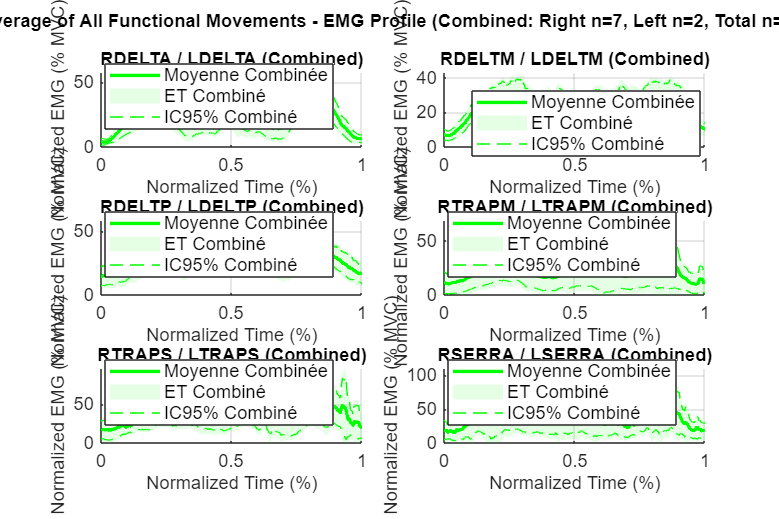


===== Sujets sélectionnés pour la moyenne globale =====
Côté DROIT : [1 2 3 6 7 9 11] (n=7)
Côté GAUCHE : [10 13] (n=2)
COMBINÉ : Total (n=9)


filename = 'average_emg_profile'

Les données ont été sauvegardées dans le fichier: average_emg_profile


Traitement terminé pour la population: pre_operation



display_option = input('Choisissez une option (1-3) : ');

% Boucle sur la population sélectionnée
for p = 1:length(populations)
    population_type = populations{p};
    fprintf('Traitement de la population: %s\n', population_type);
    
    % Configuration initiale
    [subjects, muscles_R, muscles_L, functional_labels, analytic_labels, assigned_analytics, base_path] = configureStudyParameters(population_type);
    
    % Paramètres EMG
    [fs, b, a, rms_window, num_points, time_normalized] = configureEMGParameters();
    
    % Initialisation des matrices pour stocker les données
    nb_subjects = length(subjects);
    nb_muscles = length(muscles_R);
    [mvc_R, mvc_L, emg_all_subjects_R, emg_all_subjects_L] = initializeDataArrays(nb_subjects, nb_muscles, num_points);
    
    % Calcul du MVC et SNR de calibration 3 pour chaque sujet et chaque muscle
    [mvc_R, mvc_L] = calculateMVC(subjects, muscles_R, muscles_L, assigned_analytics, b, a, rms_window, nb_subjects, nb_muscles, base_path);
    
    % --- TRAITEMENT DE TOUS LES MOUVEMENTS FONCTIONNELS ---
    
    % Initialisation des structures pour stocker les données de tous les mouvements fonctionnels
    all_functional_data_R = cell(length(functional_labels), 1);
    all_functional_data_L = cell(length(functional_labels), 1);
    
    % Boucle sur tous les mouvements fonctionnels
    for selected_functional = 1:length(functional_labels)
        % Réinitialisation des matrices pour chaque mouvement fonctionnel
        [~, ~, emg_all_subjects_R, emg_all_subjects_L] = initializeDataArrays(nb_subjects, nb_muscles, num_points);
        
        % Traitement des données pour la tâche fonctionnelle courante
        [emg_all_subjects_R, emg_all_subjects_L] = processFunctionalTask_combined(selected_functional, subjects, muscles_R, muscles_L,...
            b, a, rms_window, time_normalized, mvc_R, mvc_L, functional_labels, nb_subjects, nb_muscles, emg_all_subjects_R, emg_all_subjects_L,...
            base_path, display_option);
            
        % Stockage des données dans les structures
        all_functional_data_R{selected_functional} = emg_all_subjects_R;
        all_functional_data_L{selected_functional} = emg_all_subjects_L;
        
        % --- TRAITEMENT INDIVIDUEL DE CHAQUE MOUVEMENT FONCTIONNEL (CONDITIONNEL) ---
        if display_option == 1
            % Affichage des résultats du SNR avec mise en évidence du SERRA
            displayMVCForSERRA(emg_all_subjects_R, emg_all_subjects_L, muscles_R, muscles_L, subjects);
            
            % Calcul et affichage des profils moyens
            calculateAndDisplayAverageProfiles(time_normalized, emg_all_subjects_R, emg_all_subjects_L,...
                muscles_R, muscles_L, functional_labels, selected_functional, nb_subjects, nb_muscles);
            
            % Calcul du SNR
            calculateSNRWithCal3(subjects, muscles_R, muscles_L, selected_functional, base_path);
            
            % Calcul et affichage des ratios musculaires
            calculateMuscleRatios(emg_all_subjects_R, emg_all_subjects_L, muscles_R, muscles_L, functional_labels, selected_functional, nb_subjects);
        end
    end
    
    % --- AFFICHAGE DES GRAPHIQUES COMBINÉS ET MOYENNE GLOBALE (CONDITIONNEL) ---
    if display_option == 1 || display_option == 2
        % Appel de la fonction pour combiner les mouvements fonctionnels
        calculateAndDisplayCombinedFunctionalProfiles(time_normalized, all_functional_data_R, all_functional_data_L, muscles_R, muscles_L, functional_labels, nb_subjects, nb_muscles);
    end
    
    % Appel de la fonction qui génère le graphique et récupération des données
    [data_to_save] = calculateAndDisplayAverageFunctionalProfile(time_normalized, all_functional_data_R, all_functional_data_L, muscles_R, muscles_L, nb_subjects, nb_muscles);

    % Ajout d'informations supplémentaires si nécessaire
    data_to_save.info = 'Données du profil EMG moyen pour tous les mouvements fonctionnels';
    data_to_save.date = datestr(now);

    % Définition du nom du fichier
    filename = 'average_emg_profile'

    % Sauvegarde des données dans un fichier .mat
    save(filename, 'data_to_save');

    % Confirmation de la sauvegarde
    fprintf('Les données ont été sauvegardées dans le fichier: %s\n', filename);
    
    fprintf('Traitement terminé pour la population: %s\n\n', population_type);
end